# **ACM/IDS 104 - Problem Set 1 - MATLAB Problems**

*Before writing your MATLAB code, it is always good practice to get rid of any leftover variables and figures from previous scripts.*

clc; clear; close all;

***NOTE: ***As this is the first problem set (and many of you might be unfamiliar with MATLAB) we will provide some helper code. As the term progresses (and you become more experienced) we will omit this.

## **Problem 6 (10 points) Determinants are Expensive to Compute **

In lecture 2, we discussed that computing determinants is a computationally expensive task. Let's see how long it takes MATLAB to compute determinants of large matrices (MATLAB uses LU factorization, not the Leibniz formula of course). To do this, we will:

- Generate 25 values of $n$ logarithmically spaced between $10^2$ and $10^4$.

- For each $n,$ generate a matrix $A$ of size $n\times n,$ with entries $a_{ij}$ being sampled from the standard normal distribution. Use $\texttt{randn()}$.

- Compute $\det(A)$ and measure the time MATLAB took to complete the computatation. Use $\texttt{det(),}$ $\texttt{tic}$ and $\texttt{toc}$.

- Plot the times versus the values of $n
$ in the log-log scale. Label the axes and give a meaningful plot title.

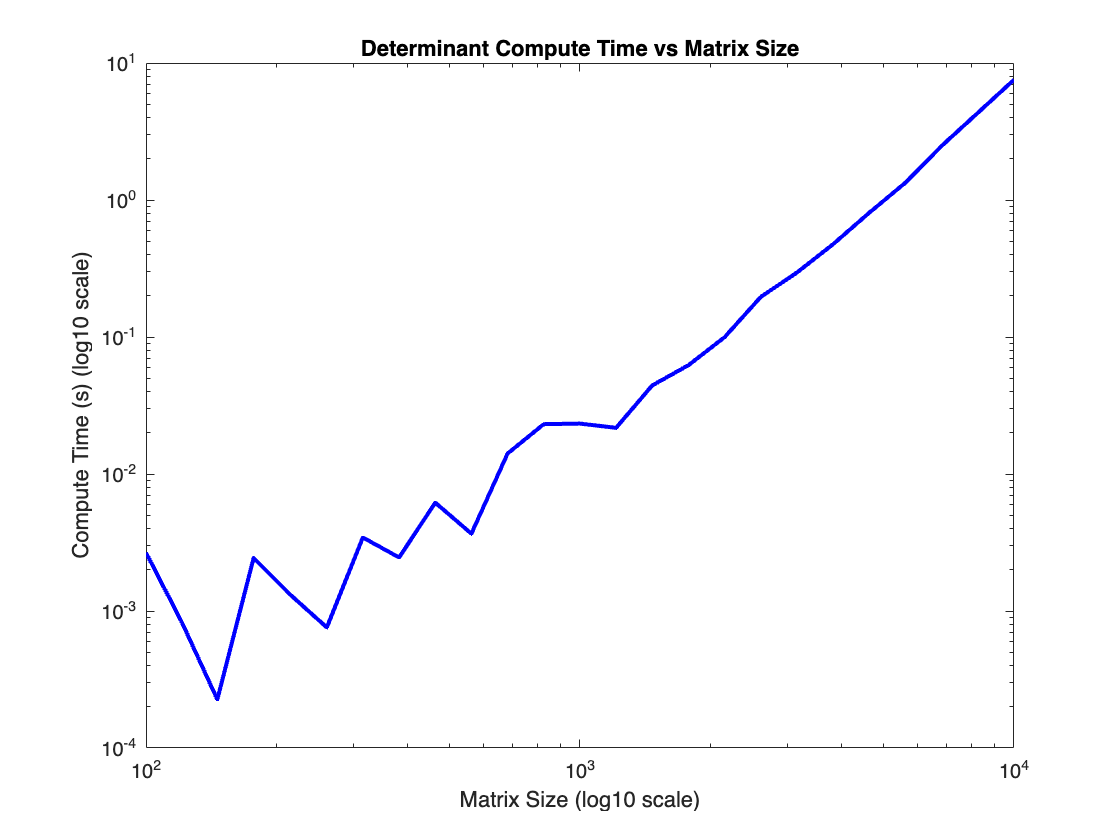

% Setup is completed for you; make sure you understand what is happening
vals = 25;
n_vals = floor(logspace(2, 4, vals));
times = NaN(vals, 1);

% TODO
for i = 1 : vals
    % Define n as the i-th element of the n_vals array
    n = n_vals(1, i);
 
    % Create the matrix A as described in step 2
    A = randn(n,n);
    
    tic; % This tells MATLAB to start the timer
    % Compute the determinant of A
    d = det(A);
    
    times(i) = toc; % This tells MATLAB to stop the timer and store the time
end


%{
PLOTTING
Here is an elementary example of how to plot in MATLAB. Feel free
to explore and customize your plots to make them more attractive!
%}

figure; % Always tell MATLAB you are starting a new figure
loglog(n_vals, times, "b", "LineWidth", 2); % log-log scale plot
xlabel("Matrix Size (log10 scale)");
ylabel("Compute Time (s) (log10 scale)");
title("Determinant Compute Time vs Matrix Size");

## **Problem 7 (10 points) Solving Linear Systems **

We have the matrix:


$$B = \pmatrix{1 & 2 & \cdots  & n \cr
n+1 &n+2&\cdots&2n\cr
\vdots & \vdots & &\vdots\cr
n^2-n+1 & n^2-n+2 & \cdots & n^2}$$


### **Part (a) (5 points)**

In this part, your task is to find $\text{rank}(B)$. As mentioned in the problem set, MATLAB is not needed to obtain the answer. However, we can use MATLAB to make a right guess and check our answer. To do this, we first need to construct matrix $B$ in MATLAB:

***NOTE: ***Although you can check your answer here, you still need to justify and show your reasoning to obtain full credit :)

n = 100; % set n as specified in Part (b)
B = 1 : n;
for i = 2 : n
    % TODO (one-liner)
    B = [B ; B(i-1, n) + 1 : B(i-1, n) + n];
end
r = rank(B); % check your answer here

### **Part (b) (5 points)**

Set $n = 100$ and consider the system of linear equations $Bx=c$ where $c = \pmatrix{1 &2&\cdots&n}^T$. Find a solution $x$ such that its first $[n-\text{rank}(B)]$ components are zero. What are the non-zero components of $x$?

***HINT: ***The backslash operator $B\backslash c$ issues a warning if $B$ is nearly singular and raises an error condition if it detects exact singularity. In that case, use $\texttt{pinv(B)*c}$ for finding a particular solution of $Bx=c
$. The function $\texttt{pinv(B)}$ returns the "pseudoinverse" of $B$ (will discuss the Moore-Penrose pseudoinverse in lecture 16). Also, the following built-in function may be useful: $\texttt{null
}$.

%{
Let us start by defining the column vector c as specified above.
Remember that in MATLAB we can use ' to transpose a vector.
%}
c = 1 : n;
c = c';

%{
Now, we obtain a particular solution, x_0, as described above
%}
x_0 = pinv(B) * c;


%{
Use null(B) to define the matrix V, whose columns form an orthonormal
basis in the vector space of all solution of the homogeneous

V =    -0.3457    0.2392   -0.1498    0.0242    0.1751   -0.1583   -0.4067   -0.0931    0.1819   -0.4261    0.0809   -0.3306   -0.1004    0.1292    0.0912    0.0241    0.0430    0.0607   -0.0388    0.0638    0.0090   -0.0438   -0.1210    0.1052    0.0286   -0.0482   -0.0148    0.0404    0.0177   -0.0168    0.0005   -0.0093   -0.0236    0.0221    0.0068    0.0238    0.0276   -0.0458   -0.0368   -0.0308   -0.0073   -0.0177    0.0124   -0.0070    0.0390   -0.0098   -0.0440    0.0168    0.0249    0.0265
   -0.1408   -0.2431   -0.0637    0.4665    0.2635   -0.1300    0.0860    0.0428    0.0829    0.3508    0.3153   -0.0251    0.0914    0.2881    0.2507   -0.2274   -0.1318    0.0026   -0.0182    0.0152   -0.0586    0.0301   -0.0281   -0.0321   -0.0761    0.0027    0.0166   -0.0609    0.0612   -0.0839   -0.0716    0.0081    0.0195   -0.0665    0.0263   -0.0267   -0.0208    0.0158    0.0415    0.0741    0.0189   -0.0046    0.0345    0.0281   -0.0041    0.0121    0.0117   -0.0037    0.0070   -0

system Bx=0.
%}
V = null(B)


%{
Use the rank, r, found in part (a) to define k = n - rank(B).
This is the number of free variables / dimension of the vector

k = 98

space.
%}
k = n - r

This is a good point to review what we have done so far. Recall that the desired solution of the system is:


$$x = x_0 + V\alpha\,\,\,\,\,(\star)$$


where $\alpha$ is a $k\times1$ vector. We can obtain $\alpha$ by solving the system:


$$ x_0 + V\alpha=0\,\,\,\,\,(\star\star)$$


%{
Find alpha by solving the described system (**).
-> Hint1: Remeber that alpha is a k*1 vector. Hence, you need to
restrict the sizes of x_0 and V
-> Hint2: Use backslash
%}
alpha = V(1:k, :) \ (-1 * x_0(1:k, :));


%{

   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
         0
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000

Finally, put everything together and find x using (*)
Use disp(x) to display your solution.
%}
x = x_0 + V * alpha;
disp(x)
%{

   9.0801e-14



Now, let us see how x compares to the actual solution.
Un-comment the following 2 lines of code once you reach this part.
%}
error = norm(B*x - c);
disp(error);

Don't forget to report the non-zero components of $x$!